Initializing variables

load('mymap.mat') % loading binary occupancy grid
occGrid = map;

rng('shuffle') % shuffling seed

check_err=0; % flag if RRT gets stuck

% x and y co-ordinates arrays for the trajectory
xcordstraj = []; 
ycordstraj = [];


xmax = 479; % max x cordinate value
ymax = 496; % max y cordinate value
nsamps = 0; % total number of samples collected so far
niters = 3000; % total number of samples to be collected
velo = 3*rand()*2e-2;% velocity of a human
firsttime = 1; % flag when the trajectory starts

timesdone = 0; % counter how many sub trajectories are within a trajectory

routecell = {}; % The cell to store all information

done = 1; % Variable to control the main loop

Main Loop

while done % checking if we need to stop the loop


    timesdone = timesdone+1; % counting sub trajectories
    stop = 1; % placeholder flag
% this while loop ensures that the starting points of each sub
% trajectories are not within a building
    while (stop) && (firsttime)

        startpoint = [ randi([20 xmax-20]) randi([20 ymax-20]) ];
        if (startpoint(1) == xmax) || (startpoint(2) == ymax) ||  (getOccupancy(occGrid,startpoint)>0.5) %(bldgvals(startpoint(1),startpoint(2)) ==1)
            stop = 1;

        else
            stop = 0;
            firsttime = 0;


        end


    end
% this while loop ensures that stopping points of each sub trajectory are
% not within the buildings
    stop = 1;

    while stop

        stoppoint = [ randi([50 xmax-50]) randi([50 ymax-50]) ];

        if (stoppoint(1) == xmax) || (stoppoint(2) == ymax) || (sqrt(sum((stoppoint-startpoint).^2)) < 300) || (getOccupancy(occGrid,stoppoint)>0.5)  %|| (bldgvals(stoppoint(1),stoppoint(2)) ==1)
            stop = 1;
        else
            stop = 0;


        end


    end
  
% assigning start and end points

    start = [startpoint 0];
    goal = [stoppoint 0];
    r = 0.5; % turning radius
    clc
    % initializing states for RRT
    bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];
    ss = stateSpaceDubins(bounds);
    ss.MinTurningRadius = 0.5;
    stateValidator = validatorOccupancyMap(ss);
    stateValidator.Map = occGrid;


    % Running RRT and avoiding buildings
    stateValidator.ValidationDistance = 0.05;
    planner = plannerRRT(ss, stateValidator);
    planner.MaxConnectionDistance = 2.0;
    planner.MaxIterations = 50000;
    planner.GoalReachedFcn = @checksifgoals;
    %rng(0,'twister')
    [pthObj, solnInfo] = plan(planner, start, goal);
    %show(occGrid)

    
    % calculating distance and times
    distance  = sqrt(sum((stoppoint-startpoint).^2));
    timeover = distance/velo;

    % error checking loop
    try
        % moving the UE over the trajecotry
        interpolate(pthObj,round(timeover))
        check_err=1;
    catch
        warning('Interpolate did not run.');
        check_err = 0;
        done = 0;
    end

    % seeing if the UE was able to move successfully
    if check_err

        nsamps = nsamps + timeover; % collected samples from sub-trajectory

        startpoint = stoppoint; % setting start point for next sub-trajectory

        routecell{end+1} = pthObj.States; % saving route information
        xcordstraj(end+1:end + length(pthObj.States(:,1))) = pthObj.States(:,1); % appending x cordinates of sub-trajectory
        ycordstraj(end+1:end + length(pthObj.States(:,2))) = pthObj.States(:,2);% appending y cordinates of sub-trajectory
    end
    % checking if enough samples are collected
    if nsamps >=niters
        done = 0;
    end


end

Plotting the whole trajectory

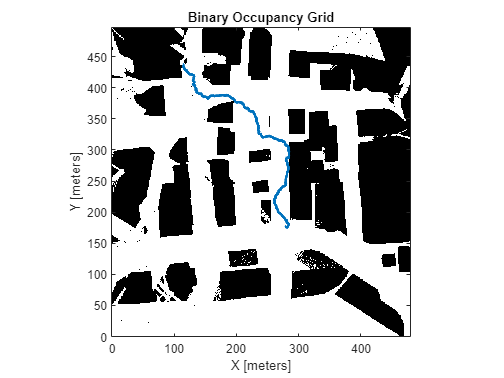


figure()
show(occGrid)
hold on
plot(xcordstraj,ycordstraj,'LineWidth',2.5)